clear all

[imgDataTrain, labelsTrain, imgDataTest, labelsTest] = prepareData;

Preparing MNIST data...
MNIST data preparation complete.



size(imgDataTrain)

ans =           28          28           1       60000


size(labelsTrain)

ans =        60000           1


size(imgDataTest)

ans =           28          28           1       10000


size(labelsTest)

ans =        10000           1


ima = imgDataTrain(:,:,1,3);
imb = imbinarize(ima)

imb = 28×28 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   0   0   0   0   0
   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   0   0   0   0   0
   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0  

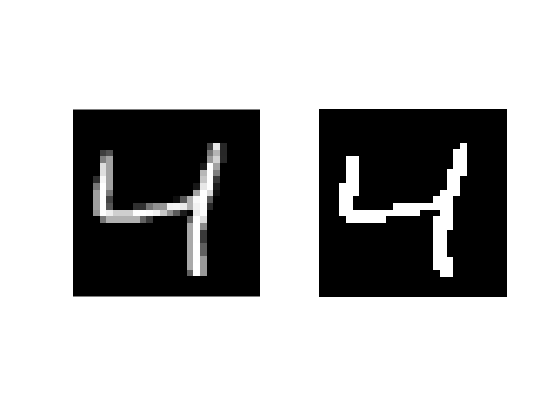


figure;
subplot(1,2,1);
imshow(ima)
subplot(1,2,2);
imshow(imb)


trainsize = size(imgDataTrain,4);
features=[]


features =

     []



for i = 1:10000
features(i,:) = extractHOGFeatures(imbinarize(imgDataTrain(:,:,1,i)),'CellSize',[7 7]);
end

idx = kmeans(features,10)

idx =      7
     8
     3
     2
     3
     6
     1
     7
     1
     4



testimages = imgDataTrain(:,:,1,idx == 4)

testimages = 28×28×1×1262 uint8 array
testimages(:,:,1,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   189   190     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

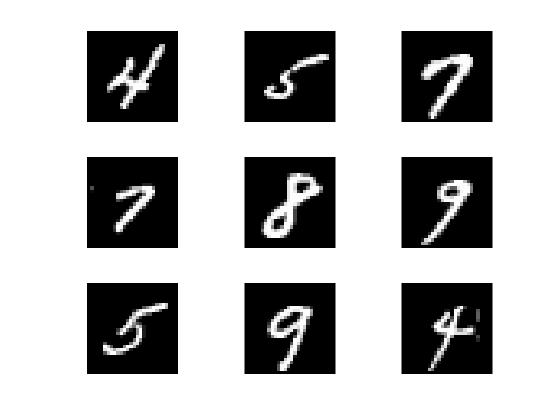


for j = 1:9
    
    subplot(3,3,j);
    imshow(testimages(:,:,:,j))
end

% Extract HOG features and HOG visualization
[hog_2x2, vis2x2] = extractHOGFeatures(ima,'CellSize',[2 2]);
[hog_4x4, vis4x4] = extractHOGFeatures(ima,'CellSize',[4 4]);
[hog_8x8, vis8x8] = extractHOGFeatures(ima,'CellSize',[7 7]);

% Show the original image
figure; 
subplot(2,3,1:3); imshow(ima);

% Visualize the HOG features
subplot(2,3,4);  
plot(vis2x2); 
title({'CellSize = [2 2]'; ['Length = ' num2str(length(hog_2x2))]});

subplot(2,3,5);
plot(vis4x4); 
title({'CellSize = [4 4]'; ['Length = ' num2str(length(hog_4x4))]});

subplot(2,3,6);
plot(vis8x8); 
title({'CellSize = [7 7]'; ['Length = ' num2str(length(hog_8x8))]});